# Assignment M6.2 (MATLAB)

## Problem M1

The mast of a sailboat is constructed of an experimental aluminum alloy. Tests were performed to define the relationship between stress and strain. The test results are

- Fit a second order polynomial to this data to express stress as a function of strain. 

- Plot the curve fit along with the data to determine visually if the curve line is appropriate to represent the data.

- Determine the coefficient of dtermination $R^2$ for the curve fit. 

- The stress can be substituted into the polynomial expression to determine the mast's deflection, which is defined as the strain multiplied by L, where L is the mast's length. If the stress on the mast caused by wind is $$2300$ $\rm{N/cm^2}$$, use the curve fit to estimate the deflection of a 9m mast ($$L=9$ $m$$).

% M1 Answer
stress = [4970, 5170, 5500, 3590, 6900, 1240];
strain = [0.0032, 0.0045, 0.0055, 0.0016, 0.0085, 0.0005];

[strain, sortIdx] = sort(strain);
stress = stress(sortIdx);

p = polyfit(strain, stress, 2);
p_fit = polyval(p, strain)

p_fit = 1.0e+03 *

    1.7539    3.0024    4.4960    5.4284    5.9739    6.7154


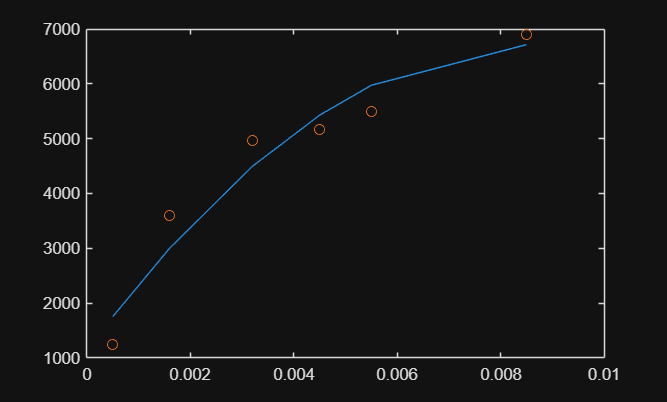


figure(1);
plot(strain, p_fit)
hold on;
scatter(strain, stress)



SStot = sum((stress - mean(stress)).^2);
SSres = sum((stress - p_fit).^2);
rsq = 1 - SSres/SStot;
disp(rsq)

    0.9385




q = polyfit(stress, strain, 2)

q =     0.0000   -0.0000    0.0011


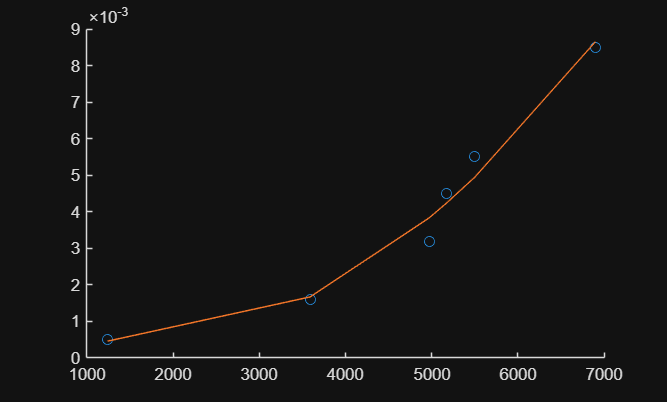


q_fit = polyval(q, stress);
figure(2);
scatter(stress, strain);
hold on;
plot(stress, q_fit);

wind_stress = 2300;
wind_strain = polyval(q, wind_stress);
L = 9;
deflection = wind_strain * L;
disp(deflection);

    0.0056



## Problem M2

The following equation of state provides a relationship between pressure (p), temperature (T) and volume (V). In this equation a,b and c are unknown paramters which need to be determined using the data provided below.


$$P=RT\left(\frac{a}{V}+\frac{b}{V^2}+\frac{c}{V^3}\right)$$


`where `$R = 82.05\, \rm{[mL.atm/gmol.K]}$` and `$T = 303\,[K]$`.`

- Use nonlinear regression to find a ,b,c; (use initial parameter guesses of (a=1,b=1,c=1)).

- Check the accuracy of the fits by plotting the curves along with the data.

- Check the $R^2$ value and together with the plot decide on the usefulness of the fit.

% M2 Answer
V_data = [25000 22200 18000 15000];
P_data = [0.985 1.108 1.363 1.631];

R = 82.05;
T = 303;

modelfun = @(b, V)R*T*(b(1)./V + b(2)./V.^2 + b(3)./V.^3);

beta0 = [1 1 1];

mdl = fitnlm(V_data, P_data, modelfun, beta0)

mdl = Nonlinear regression model:
    y ~ R*T*(b1/V + b2/V^2 + b3/V^3)

Estimated Coefficients:
           Estimate          SE           tStat         pValue  
          ___________    __________    ___________    __________

    b1        0.99868    7.3339e-05          13617    5.3928e-09
    b2        -180.78         1.292        -139.92    5.1075e-05
    b3    -5.7699e+05    0.00014065    -4.1023e+09    5.9421e-20


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 3.46e-05
R-Squared: 1,  Adjusted R-Squared 1
F-statistic vs. zero model: 2.81e+09, p-value = 3.56e-10

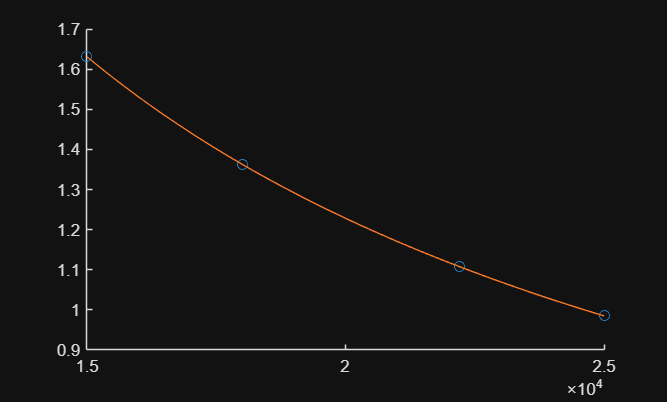


V_fit = linspace(min(V_data), max(V_data), 200)';
P_fit = predict(mdl, V_fit);

figure;
scatter(V_data, P_data);
hold on;
plot(V_fit, P_fit);

## Problem M3

A simply supported steel beam of length L = 2m is subjected to a transverse load. Small vertical deflections w(x) are measured with a displacement gauge at several locations along the span (positive downward) as provided by the following data. 

- Fit a cubic spline curve to the data.Supports are at x=0 and x=L providing 'not-a-knot' end conditions for the spline fit. 

- Plot the data along with the spline curve on the samw plot.

- Determine the deflection w (in mm) at x=1.7m.

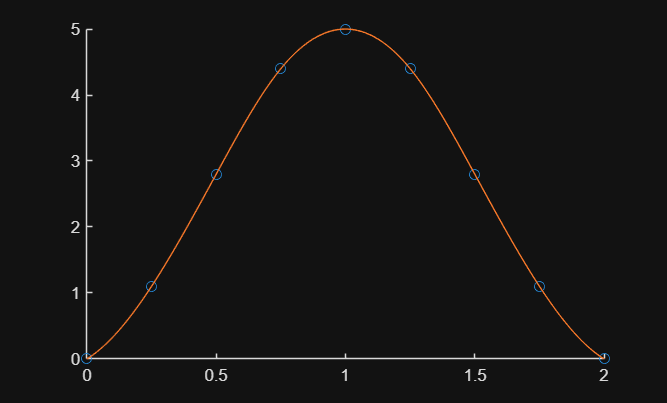

% M3 Answer
x_data = [0 0.25 0.5 0.75 1 1.25 1.5 1.75 2.0];
w_data = [0 1.1 2.8 4.4 5.0 4.4 2.8 1.1 0];
L = 2;

pp = spline(x_data, w_data);
xq = linspace(min(x_data), max(x_data), 400);
yq = ppval(pp, xq);

figure;
scatter(x_data, w_data);
hold on;
plot(xq, yq);


w_at_17 = ppval(pp, 1.7);
disp(w_at_17);

    1.4112

